# Capacity Measurements

## Initializing the Network: 

clear 
clc
rng(2,"twister");

net = IzhikevichNetwork(400);
net.SetInitialConnectivity(0.5, 2, 2);
net.STDP = true;
net.stimulation = true;
net.sampling = false;

## Sequential Learning

Feeding the stimulations to the network to learn In series and independently.


M_max = 5; % maximum number of memory to encode in the network
stims = []; 
interval = 100; %ms
N_trials = 1000;

for m = 1:M_max
    stims = [stims, Stimulation(net, interval, 2, 30, 50, 0)];
  
    net.run(N_trials*interval);
    net.stims = []; % clear the stims list as it slows down the computaiton speed
end

## Retrieval of Memories by brief kicks

Retrieval of memories by N_retreivals stimulations per stim (In series)

N_retrievals = 10; % number of retrieval per memory
for m = 1:M_max
    stims(m).on = true;
    net.stims = [stims(m)];
    net.run(interval*N_retrievals)
end

data = net.getData();

## Alternating Learning

Feeding the stims to the network to learn (In Parallel)

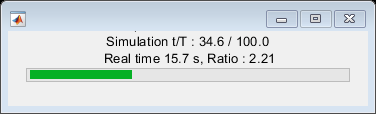

M_max = 5; % maximum number of memory to encode in the network
stims = []; 
interval = M_max*100; %ms
N_trials = 1000;

for m = 1:M_max
    stims = [stims, Stimulation(net, interval, 2, 30, 50, (m-1)*100)];
end 

for m = 1:M_max
    net.run(N_trials * 100)
end


data = net.getData();

## Computing the order vectors :)

firings = transpose(data.firings);
interval = 100; % ms 
off_set_time = 0;

check_flag_save = zeros(round(net.t/interval), net.N);
total_spike_count = zeros(1, round(net.t/interval));
ex_neurons_engagement_count = zeros(1, round(net.t/interval));
inh_neurons_engagement_count = zeros(1, round(net.t/interval));

f = waitbar(0, "Computing First to Spike Orders ...");
for trial_number = 1:round(net.t/interval)
    % Computing the orders
    check_flag = zeros(1, net.N);
    
    indices = (firings(:, 1) > (trial_number-1) * interval + off_set_time) & (firings(:, 1) <= trial_number * interval + off_set_time);
    spike_times = firings(indices, 1) - (trial_number-1)*interval - off_set_time;
    neuron_indices = firings(indices, 2);    
    
    counter_ex = 1;
    counter_inh = net.Ne+1;
  
    neuron_sorted_indices = zeros(size(spike_times, 1), 1);
   
    for i = 1:length(spike_times)
        if true
            if neuron_indices(i) <= net.Ne
                if check_flag(neuron_indices(i)) == 0 % First excitatory spikes
                    neuron_sorted_indices(i) = counter_ex;
                    check_flag(neuron_indices(i)) = counter_ex;
                    counter_ex = counter_ex + 1;
                else % Repeated excitatory spikes
                    neuron_sorted_indices(i) = check_flag(neuron_indices(i));
                end
            else
                if check_flag(neuron_indices(i)) == 0 % First Inhibitory spikes
                    neuron_sorted_indices(i) = counter_inh;
                    check_flag(neuron_indices(i)) = counter_inh;
                    counter_inh = counter_inh + 1;
                else % Repeated Inhibitory spikes
                    neuron_sorted_indices(i) = check_flag(neuron_indices(i));
                end
            end
        end
    end
    
    check_flag_save(trial_number, :) = check_flag;
    total_spike_count(trial_number) =  length(spike_times);
    ex_neurons_engagement_count(trial_number) = sum(unique(neuron_indices)<=net.Ne);
    inh_neurons_engagement_count(trial_number) = sum(unique(neuron_indices)>net.Ne);
    
    waitbar(trial_number/round(net.t/interval), f, sprintf("Computing First to Spike Orders ..., trial %d", trial_number))
end

close(f)

## Spearman Corr Matrix   

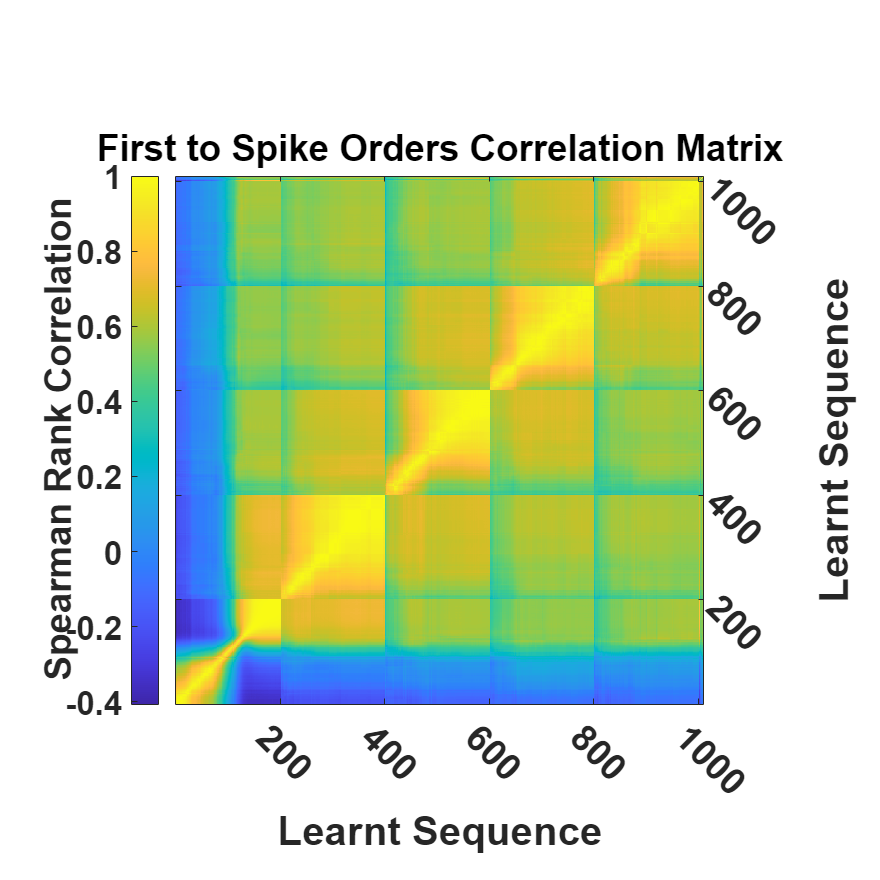

corrmat = corr(check_flag_save(:, 1:400)','type', 'spearman');

submat = corrmat(2 :5:end, 1:5:end);
%submat(logical(eye(size(submat, 1)))) = 0;

% Create the heatmap

figure('Renderer', 'painters', 'Position', [100 100 1000 1000]); % Adjust position and size as needed
fsize = 25; % font size


% Create axes with the desired position and size
ax = axes('Position', [0.2, 0.2, 0.6, 0.6]); % [left, bottom, width, height]

%imagesc(submat, 'Parent', ax, 'AlphaData', ~isnan(submat));
imagesc(submat, 'Parent', ax)
colormap(parula);
c = colorbar;

% Adjust the position of the colorbar to the left
c.Units = 'normalized'; % Use normalized units
c.Position = [0.15, 0.2, 0.03, 0.6]; % [left, bottom, width, height]
% Move the colorbar title to the middle and set font properties

c.Label.String = 'Spearman Rank Correlation';
c.Label.Rotation = 90; % Rotate the label to be vertical
c.Label.Position = [-2, 0.3, 0]; % Adjust the position to be centered and beside the colorbar
c.Label.FontName = 'Arial'; % Set the font name
c.Label.FontSize = fsize; % Set the font size
c.Label.FontWeight = 'bold'; % Set the font weight to bold

% Set the title and axis labels with consistent font properties
xlabel('Learnt Sequence', 'FontName', 'Arial', 'FontSize', fsize, 'FontWeight', 'bold');
ylabel('Learnt Sequence', 'FontName', 'Arial', 'FontSize', fsize, 'FontWeight', 'bold', 'Rotation', 90);


set(gca, 'YDir', 'normal')

xtickangle(-45)
set(gca, 'FontName', 'Arial', 'FontSize', fsize, 'FontWeight', 'bold'); % Set for x-tick labels

% Similarly, you can set y-ticks if needed
% yticks(xTickPositions);
% yticklabels(xTickLabels);
ytickangle(-45)
set(gca, 'FontName', 'Arial', 'FontSize', fsize, 'FontWeight', 'bold'); % Set for y-tick labels

% Set x-ticks to top and y-ticks to right
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'right');

% Adjust paper size and position for saving as PDF
set(gcf, 'PaperPositionMode', 'auto');
set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0 0 10 10]); % [left, bottom, width, height]
set(gcf, 'PaperSize', [10 10]); % [width, height]


title("First to Spike Orders Correlation Matrix", 'FontName', 'Arial', 'FontSize', fsize, 'FontWeight', 'bold')
print(gcf, 'Spearman_Corr_Matrix.png', '-dpng', '-r300');

## PCA on order vectors (For Sequential Learning)

% Perform PCA
[coeff, score, latent, tsquared, explained, mu] = pca(check_flag_save(1:M_max*N_trials, 1:400));

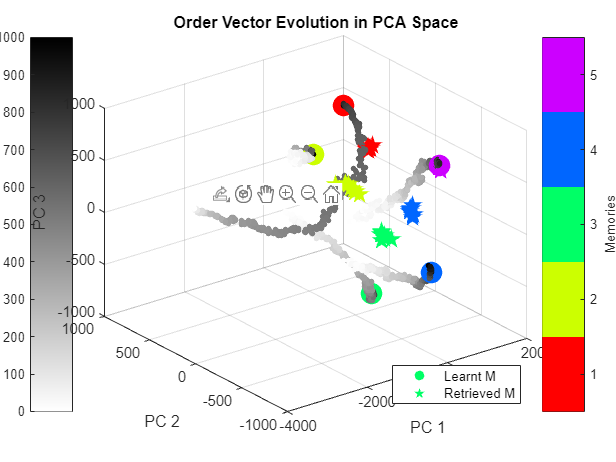


% coeff    - Principal component coefficients (eigenvectors)
% score    - Principal component scores (projected data)
% latent   - Principal component variances (eigenvalues)
% tsquared - Hotelling's T-squared statistic for each observation
% explained- Percentage of total variance explained by each principal component
% mu       - Estimated mean of each variable

x = score(:, 1);
y = score(:, 2);
z = score(:, 3);

mem_colors = hsv(M_max);
colors = zeros(N_trials*M_max, 3);
for m = 1:M_max
    colors((m-1)*N_trials+1:m*N_trials, :) = [flip(gray(N_trials-1)); mem_colors(m, :)];
end

figure;
ax1 = axes;
ax2 = axes;
ax2.Position = ax1.Position; % Align the second axes with the first
ax2.Color = 'none'; % Make the background of the second axes transparent
linkprop([ax1, ax2], {'CameraPosition', 'CameraTarget', 'CameraUpVector', 'CameraViewAngle'});


for m = 1:M_max
    indices = m:M_max:M_max*N_trials;
    scatter3(x(indices), y(indices), z(indices),10, colors(indices, :), Marker="o", MarkerFaceColor="flat", HandleVisibility='off');
    %plot3(x(indices), y(indices), z(indices), 'k' )
    hold on
end

hold on


indices = N_trials:N_trials:M_max*N_trials; % for in series mode

% scatter3(ax2, x(indices), y(indices), z(indices), 200, colors(indices,
% :), Marker="o", MarkerFaceColor="flat", DisplayName= "Learnt M",
% HandleVisibility='on'); % in parralel
scatter3(ax2, x(indices), y(indices), z(indices), 200, colors(indices, :), Marker="o", MarkerFaceColor="flat", DisplayName= "Learnt M", HandleVisibility='on'); % in series

%%%%%%%%%%%%%%%%% Plotting retrieved sequences
temp = check_flag_save(M_max*N_trials+1:end, :);
test_data_centered = bsxfun(@minus, temp, mu);
score = test_data_centered * coeff;
x = score(:, 1);
y = score(:, 2);
z = score(:, 3);

c = [];
for m = 1:M_max
    c = [c;repmat(mem_colors(m, :), N_retrievals, 1)];
end

scatter3(ax2, x, y, z, 150, c, marker="pentagram", MarkerFaceColor="flat", DisplayName='Retrieved M')


colormap(ax1, flipud(gray))
clim(ax1,[0 1000]);
cb1 = colorbar(ax1,'Position',[.05 .11 .0675 .810]);
ylabel(cb1, 'Trial Number');

colormap(ax2, mem_colors)
clim(ax2, [0 M_max]);
cb2 = colorbar(ax2,'Position',[.88 .11 .0675 .810]);
cb2.Ticks = 0.5:1:M_max-0.5;
cb2.TickLabels = 1:M_max ;
ylabel(cb2, 'Memories');

%%Then add colorbars and get everything lined up
set([ax1,ax2],'Position',[.17 .11 .685 .815]);


xlabel('PC 1');
ylabel('PC 2');
zlabel('PC 3')
title('Order Vector Evolution in PCA Space');
legend(Location='best')

## PCA on order vectors (For Alternating Learning)

% Perform PCA
[coeff, score, latent, tsquared, explained, mu] = pca(check_flag_save(1:M_max*N_trials, 1:320));

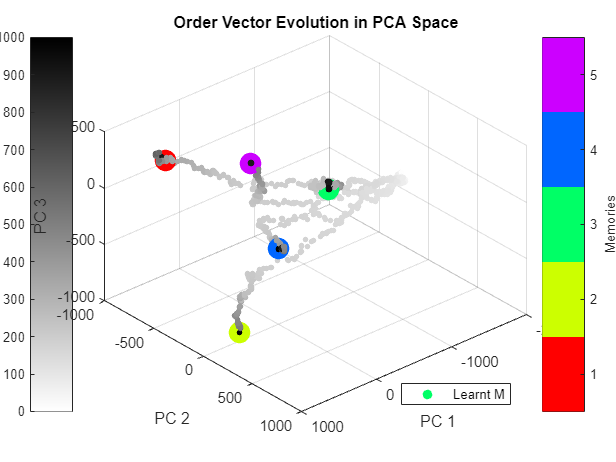


% coeff    - Principal component coefficients (eigenvectors)
% score    - Principal component scores (projected data)
% latent   - Principal component variances (eigenvalues)
% tsquared - Hotelling's T-squared statistic for each observation
% explained- Percentage of total variance explained by each principal component
% mu       - Estimated mean of each variable

x = score(:, 1);
y = score(:, 2);
z = score(:, 3);

mem_colors = hsv(M_max);
colors = zeros(N_trials*M_max, 3);
for m = 1:M_max
    colors(m:M_max:end, :) = [flip(gray(N_trials-1)); mem_colors(m, :)];
end

figure;
ax1 = axes;
ax2 = axes;
ax2.Position = ax1.Position; % Align the second axes with the first
ax2.Color = 'none'; % Make the background of the second axes transparent
linkprop([ax1, ax2], {'CameraPosition', 'CameraTarget', 'CameraUpVector', 'CameraViewAngle'});


for m = 1:M_max
    indices = m:M_max:M_max*N_trials;
    scatter3(x(indices), y(indices), z(indices),10, colors(indices, :), Marker="o", MarkerFaceColor="flat", HandleVisibility='off');
    %plot3(x(indices), y(indices), z(indices), 'k' )
    hold on
end

hold on

indices = N_trials*M_max-M_max+1:N_trials*M_max;

scatter3(ax2, x(indices), y(indices), z(indices), 200, colors(indices, :), Marker="o", MarkerFaceColor="flat", DisplayName= "Learnt M", HandleVisibility='on'); % in series

colormap(ax1, flipud(gray))
clim(ax1,[0 1000]);
cb1 = colorbar(ax1,'Position',[.05 .11 .0675 .810]);
ylabel(cb1, 'Trial Number');

colormap(ax2, mem_colors)
clim(ax2, [0 M_max]);
cb2 = colorbar(ax2,'Position',[.88 .11 .0675 .810]);
cb2.Ticks = 0.5:1:M_max-0.5;
cb2.TickLabels = 1:M_max ;
ylabel(cb2, 'Memories');

%%Then add colorbars and get everything lined up
set([ax1,ax2],'Position',[.17 .11 .685 .815]);


xlabel('PC 1');
ylabel('PC 2');
zlabel('PC 3')
title('Order Vector Evolution in PCA Space');
legend(Location='best')

## Kmean Clustering

idx = kmeans(check_flag_save(5001:end, :), 'Distance','cityblock');

Error using internal.stats.parseArgs
Wrong number of arguments.

Error in kmeans (line 181)
    = internal.stats.parseArgs(pnames, dflts, varargin{:});

figure; histogram(idx, 10)
